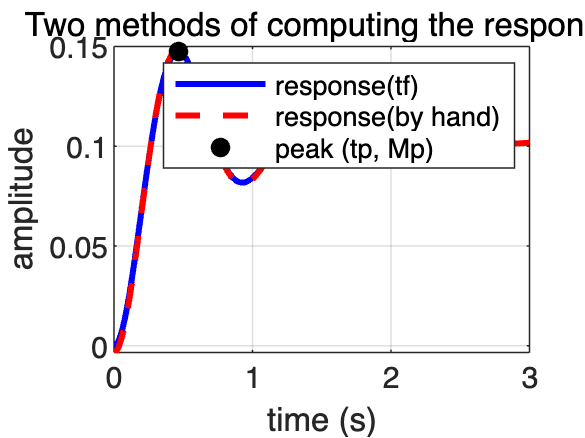

% 参数定义
g = 9.81; % m/s^2, 重力加速度
m = 5; % kg, 质量
l = 0.4; % m, 长度
c = 0.7; % Nm/rad, 阻尼系数
I = m * (l/2)^2; % 惯量矩

% 计算动态特性
wn = sqrt(m * g * l / (2 * I)); % 自然频率 (rad/s)
xi = c / (2 * I * wn); % 阻尼比
wd = wn * sqrt(1 - xi^2); % 阻尼频率 (rad/s)
tp = pi / wd; % 峰值时间
ts = 3 / (xi * wn); % 稳定时间（约5%容差）

% 计算直流增益 K
K = 5 / wn^2; % 稳态值

% 计算超调量 Mp（百分比）
Mp = 100 * exp(-xi * pi / sqrt(1 - xi^2)); % 标准超调量公式

% 传递函数
sys = tf(1/I, [1, 2*xi*wn, wn^2]);

% 计算阶跃响应
t = 0:0.01:3; % 时间向量
[y, t] = step(sys, t); % 传递函数响应

% 修正的手算响应（考虑直流增益 K）
y_manual = K * (1 - (exp(-xi * wn * t) / sqrt(1 - xi^2)) .* (cos(wd * t) + (xi / sqrt(1 - xi^2)) * sin(wd * t)));

% 绘制阶跃响应
figure;
plot(t, y, 'b-', 'LineWidth', 2, 'DisplayName', 'response(tf)');
hold on;
plot(t, y_manual, 'r--', 'LineWidth', 2, 'DisplayName', 'response(by hand)');
grid on;

% 标注关键点
peak_value = K * (1 + Mp / 100); % 修正峰值
plot(tp, peak_value, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'peak (tp, Mp)');

% 图表设置
title('Two methods of computing the response');
xlabel('time (s)');
ylabel('amplitude');
legend('show');
hold off;

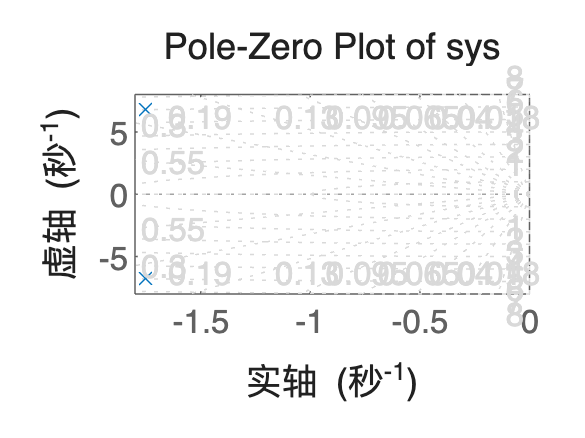


% 绘制 sys 的极-零点图
figure;
pzplot(sys);
title('Pole-Zero Plot of sys');
grid on;

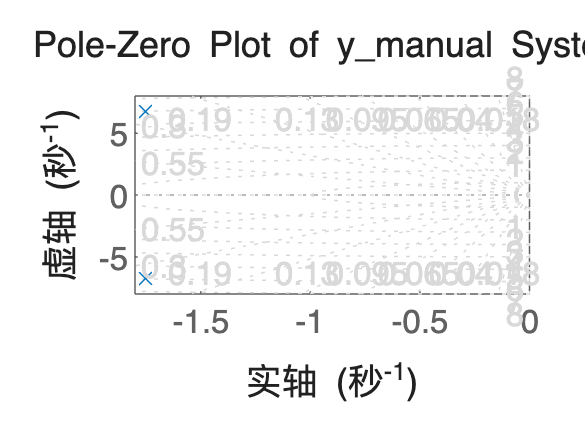


% 绘制 y_manual 的极-零点图
num = K * wn^2; % 分子是 K * wn^2
den = [1, 2*xi*wn, wn^2]; % 分母是 s^2 + 2*xi*wn*s + wn^2
sys_manual = tf(num, den);

figure;
pzplot(sys_manual);
title('Pole-Zero Plot of y\_manual System');
grid on;